# Modeling with continuous data(error_degree)

To start the tutorial we will focus on only one of these tasks, **a continuous partial report task** with colors. In such a task, observers see the stimulus display, and then after a delay are asked to report the exact color of a single item. 

Error is quantified as the distance between the response and the correct answer, in degrees on the color wheel. 

The simplest way to use the MemToolbox with such data is through MemFit, a function that houses much of the toolbox’s functionality under one roof. 

To use MemFit with continuous report data, first specify your data as a vector of response errors, one for each trial, e.g. in units of degrees on the color wheel between –180 and 180.

## StandardMixtureModel with MAP

Return the maximum a posteriori and credible intervals of the model parameter values inferred from the data.

(1) Precision parameter, sd (in degree). Bigger sd means more dispersed distribution.

(2) Guessing parameter, g (0-1), the "proportion of guesses”. higher g means lower biggest value at the center of error distributions


Error histogram:   -180 _________.'_.________ +180
          Model:   Standard mixture model
     Parameters:   g, sd

Just a moment while MTB fits a model to your data...

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
       g	       0.486	   0.009	   0.719
      sd	       7.758	   5.664	  76.039



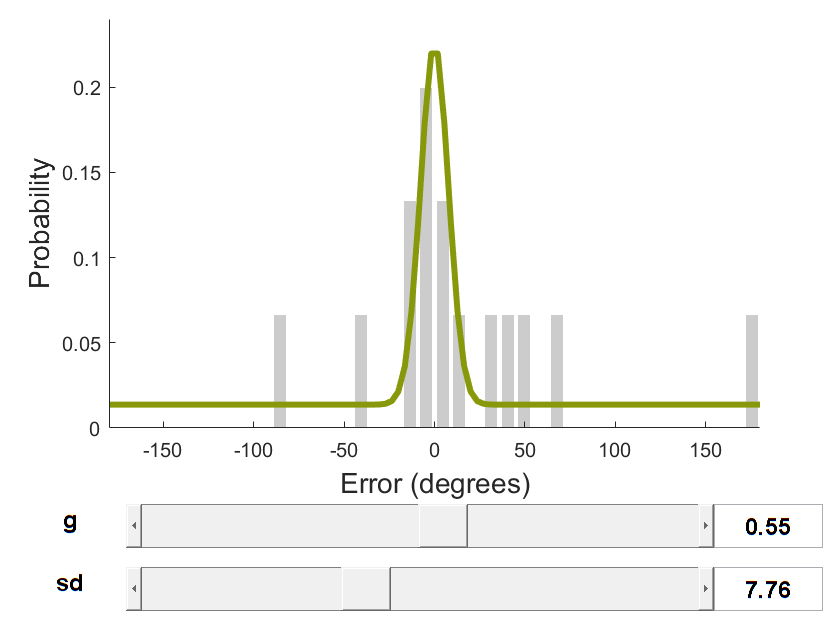


This analysis was performed using MemToolbox version 1.0.0.



clear all;
errors = [-89, 29, -2, 6, -16, 65, 43, -12, 10, 0, 178, -42, 52, 1, -2];
MemFit(errors);

## StandardMixtureModel with the MLE

Output: Return the Maximum likelihood parameters for this observer’s data No model passed in. Assuming StandardMixtureModel(). ans = 0.5267 7.8608

clear all;
errors = [-89, 29, -2, 6, -16, 65, 43, -12, 10, 0, 178, -42, 52, 1, -2];
fit = MLE(errors);

No model passed in. Assuming StandardMixtureModel().


% or define the model:
model = StandardMixtureModel();
data.errors = [-89, 29, -2, 6, -16, 65, 43, -12, 10, 0, 178, -42, 52, 1, -2];
fit = MLE(data, model)

fit =     0.5267    7.8608


data

data = struct with fields:
    errors: [-89 29 -2 6 -16 65 43 -12 10 0 178 -42 52 1 -2]


## StandardMixtureModel with further understanding

More importance of data structure could be viewed at swapping model section below 

Chains refers to Markov Chain Monte Carlo, which you can read about on Wikipedia ([http://en.wikipedia.org/wiki/Markov_chain_Monte_Carlo](http://en.wikipedia.org/wiki/Markov_chain_Monte_Carlo)). The default MCMC algorithm used by MemToolbox uses multiple chains **whose starting values are specified** in the model file (and modifiable), and it **continues running them until they have converged to a similar range of parameters**. 

**Figure 1 **

**Interactive figure**, the predicted parameter/distribution, and the real data. it lets you manipulate the values of the model parameters and see the impact on the predicted distribution of data. As you change the values, notice that the prediction line changes color — it gets less saturated (close to grey) as you choose values that make the data less likely. 

**Figure 2** 

**Posterior distribution for each parameter and a heat map for each pair of parameters,** showing how they covary. These plots are useful for diagnosing correlations between parameters. 

On the diagonal are plots that show the **posterior for an individual parameter** — e.g., the distribution for guess rate (g) the data make us quite confident that the guess rate is between 0.08 and 0.11. 

On the off-diagonal are the** correlations between the parameters** – for example, the top right axis shows guess rate (y-axis) plotted against standard deviation (x-axis). The off-diagonals show heatmaps to visualize correlations between parameters. For The data is generally equally consistent with a slightly higher guess rate and slightly lower standard deviation 

**Figure 3** 

shows the parameters of the model in a **parallel coordinates plot** ([http://en.wikipedia.org/wiki/Parallel_coordinates](http://en.wikipedia.org/wiki/Parallel_coordinates)), along with a visualization of the parameters fit to the data. 

**Each line on the parallel coordinates plot corresponds to a reasonable set of parameters for fitting the data, more likely parameter combinations get darker colors**. The negative correlation between the parameters of this particular model is indicated by the fact that the lines tend to have slopes that differ from zero (e.g., high values on one parameter give low values on the other, and vice versa). A positive correlation would be shown by the lines being mostly parallel between the left and right sides, meaning high values of one parameter give high values of the other. 

**Figure 4** 

The posterior predictive distribution—the model’s residual. 

The former two plots provide ways of** examining which parameter values of the model provide the best fits**. This figure instead shows **whether or not the model—with its best parameter values—provides a good fit to the data.** 

In particular, we **simulate ‘fake’ data from the posterior of the model** and ask whether it looks like the real data. If the model provides a good fit, then the data that is simulated using the best fit parameters (the posterior) will closely resemble the actual data. The top of the plot shows the data in black, and the simulated data in green. They should be on top of each other if the model provides a good fit. 

The bottom of the plot shows the difference between the two, both on **average (grey line) and with 95% confidence intervals** (grey shading). **Any regions where the gray shading does not include zero are regions where the model is systematically incorrect in its predictions**

clear all;
data = MemDataset(1);
data

data = struct with fields:
       errors: [3120×1 double]
    subjectID: 's1'
            n: [3120×1 double]


model=WithBias(StandardMixtureModel('UseKappa', true))

model = struct with fields:
            name: 'Standard mixture model (kappa) with bias'
      paramNames: {'mu'  'g'  'K'}
      lowerbound: [-180 0 0]
      upperbound: [180 1 Inf]
         movestd: [1 0.0200 0.1000]
             pdf: @WithBias/NewPDF
           start: [3×3 double]
       generator: @(params,dims,displayInfo)(wrap(model.oldGenerator(params(2:end),dims,displayInfo)+params{1}))
          oldPdf: @(data,g,K)((1-g).*vonmisespdf(data.errors(:),0,K)+(g).*unifpdf(data.errors(:),-180,180))
      priorForMu: @(p)(1)
    oldGenerator: @StandardMixtureModelGenerator



Error histogram:   -180 _________.'._________ +180
          Model:   Standard mixture model (kappa) with bias
     Parameters:   mu, g, K

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 10.26
   ... not yet converged (400); btw/within variance: 4.21
   ... not yet converged (600); btw/within variance: 2.06
   ... chains converged after 800 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
      mu	       2.843	   2.183	   3.421
       g	       0.091	   0.080	   0.107
       K	      11.281	  10.678	  12.283



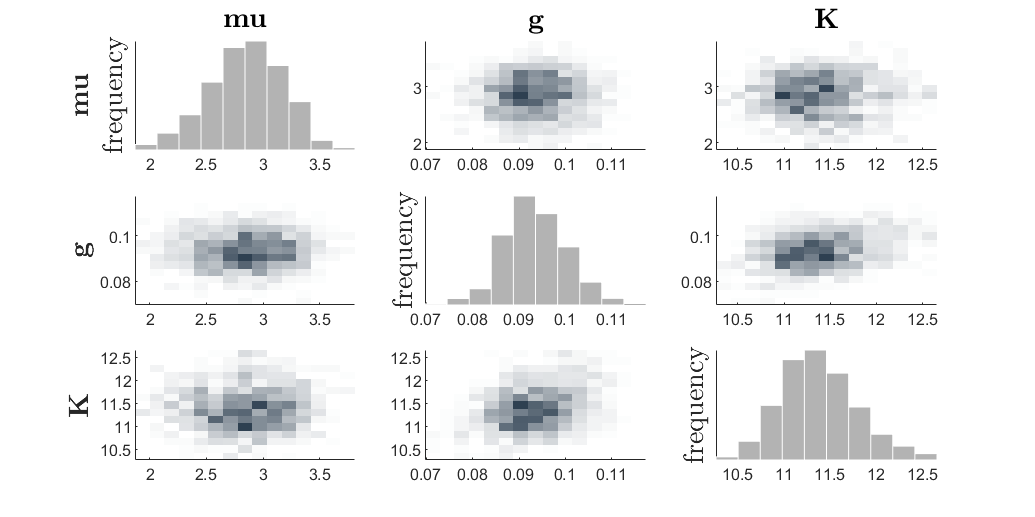

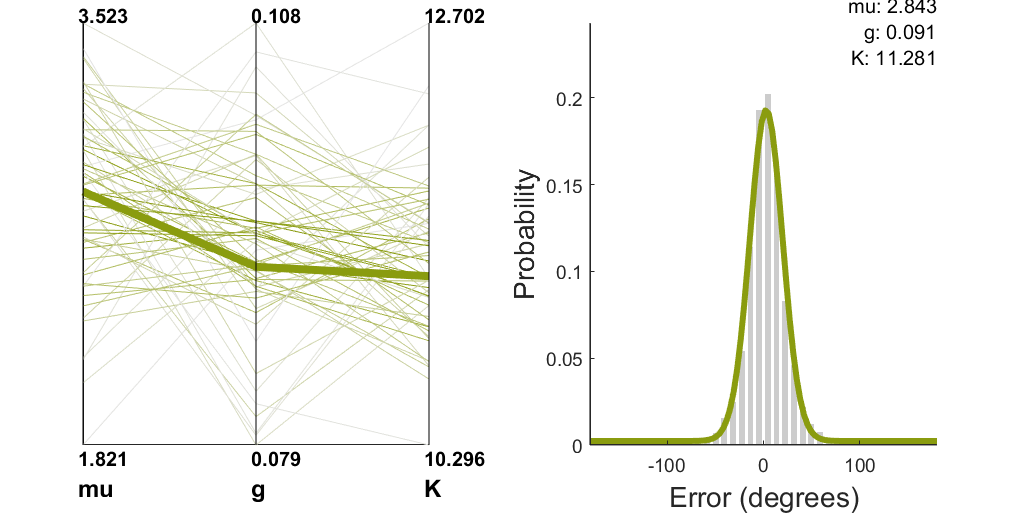

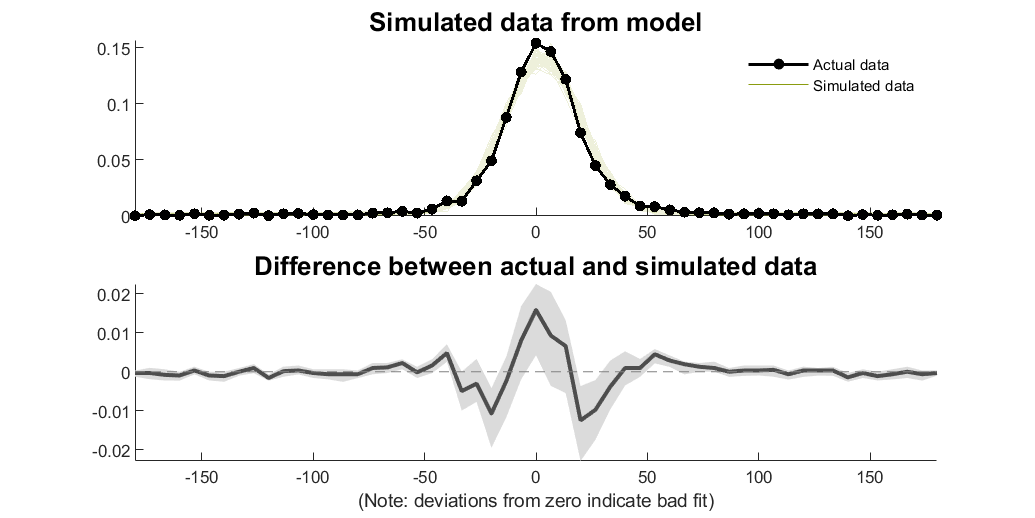


This analysis was performed using MemToolbox version 1.0.0.



fit = struct with fields:
       posteriorMean: [2.8501 0.0934 11.3807]
     posteriorMedian: [2.8622 0.0930 11.3464]
        maxPosterior: [2.8429 0.0912 11.2813]
       lowerCredible: [2.1829 0.0802 10.6775]
       upperCredible: [3.4213 0.1070 12.2834]
    posteriorSamples: [1×1 struct]


fit = MemFit(data, model)

## StandardMixtureModel() WithBias

One of the available models extends the standard mixture by **allowing a bias term**, such that the central tendency of the data isn’t fixed at zero. 


Error histogram:   -180 _________.'._________ +180
          Model:   Standard mixture model with bias
     Parameters:   mu, g, sd

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 2.36
   ... not yet converged (400); btw/within variance: 2.38
   ... not yet converged (600); btw/within variance: 2.26
   ... not yet converged (800); btw/within variance: 1.29
   ... not yet converged (1000); btw/within variance: 1.11
   ... chains converged after 1200 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
      mu	       2.828	   2.106	   3.566
       g	       0.091	   0.080	   0.107
      sd	      17.424	  16.798	  17.977



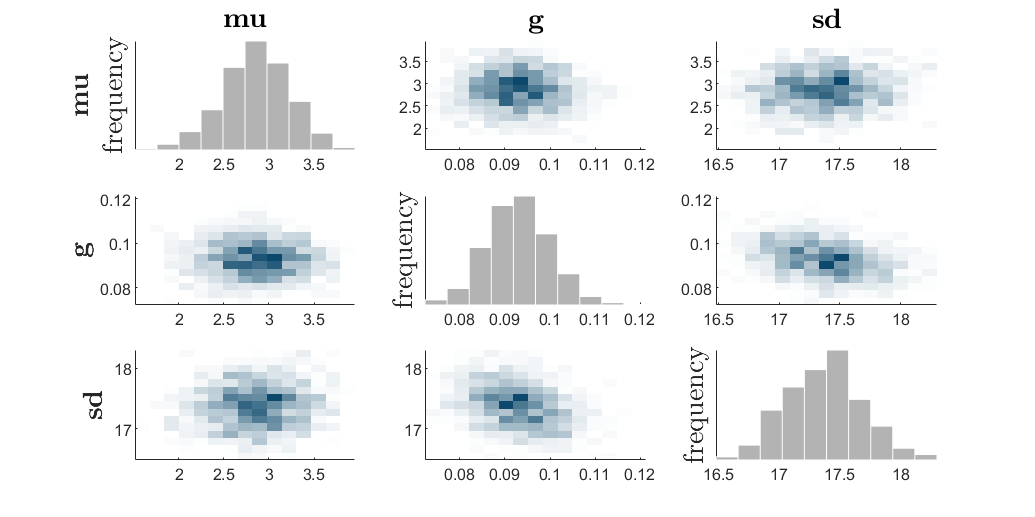

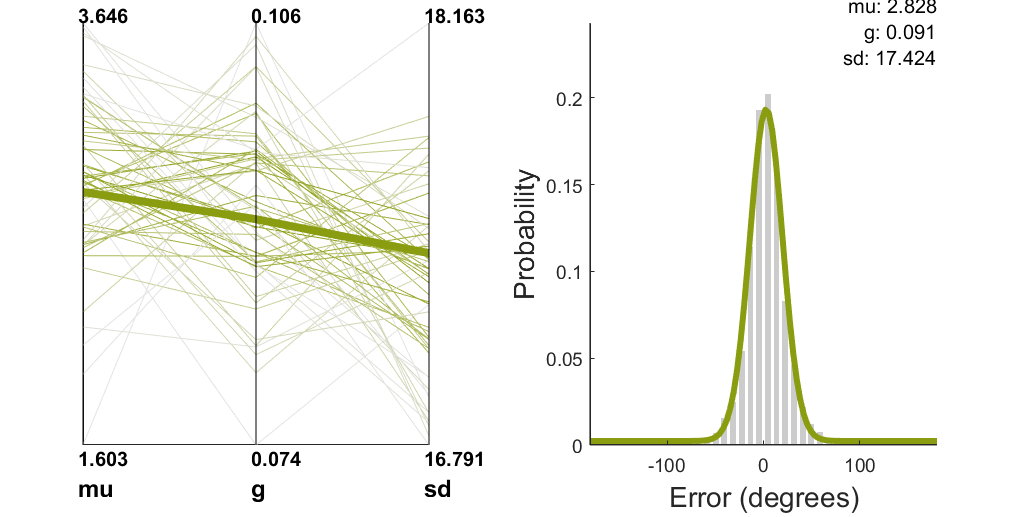

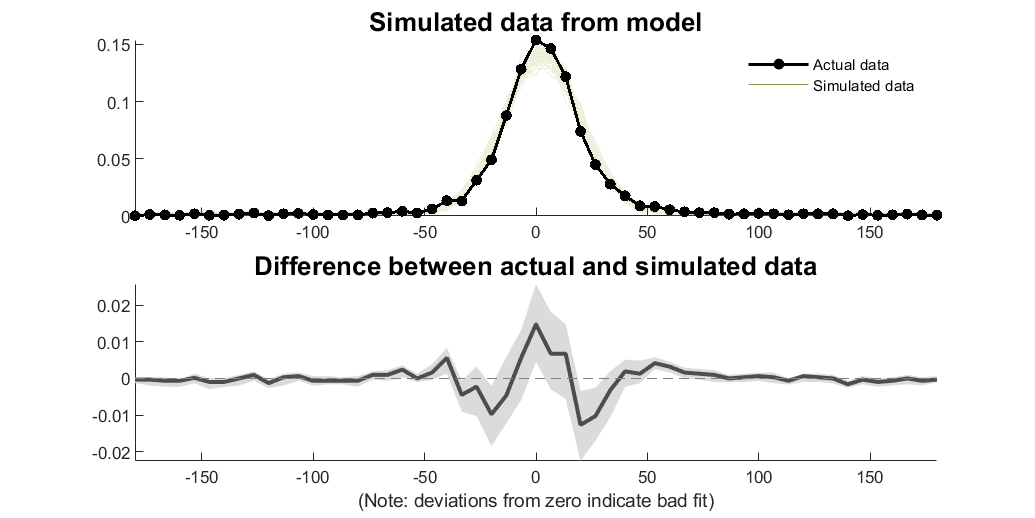


This analysis was performed using MemToolbox version 1.0.0.



% Error histogram:   -180 _________.'_.________ +180
%           Model:   Standard mixture model with bias
%      Parameters:   mu, g, sd
% 
% mu: the bias 

model = WithBias(StandardMixtureModel());
errors = MemDataset(1);
MemFit(errors, model);

## Swaping model

Swap model advocated by Bays, Catalao and Husain (2009), which holds that **participants sometimes mistakenly report the value of the other items in the display instead of the target item**. This model requires not only the **errors** but also **the distances of the non-target items from the target value**. the errors and the non-target values, should be bundled together into a structure: 

>> data.errors = [-89, 29, -2, 6, -16 ... 

>> data.distractors = [-10, 2, -100, 163, 42 ... 

the distractor on the first trial was 10 degrees counterclockwise in color space from the target color, and that the observer chose a color 89 degrees counterclockwise of this target color.

clear all;
data = MemDataset(3)

data = struct with fields:
         errors: [1×4000 double]
    distractors: [2×4000 double]
              n: [1×4000 double]
           time: [1×4000 double]


MemFit(data, SwapModel);


Error histogram:   -180 ________.-'-.________ +180
          Model:   Swap model
     Parameters:   g, B, sd

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 4.94
   ... not yet converged (400); btw/within variance: 9.05
   ... not yet converged (600); btw/within variance: 4.72
   ... chains converged after 800 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
       g	       0.097	   0.078	   0.117
       B	       0.108	   0.092	   0.124
      sd	      23.705	  22.898	  24.645



This analysis was performed using MemToolbox version 1.0.0.



help SwapModel

## Full list of models

help MemModels

  MemModels
 
  One component models:
    AllGuessingModel        - only guessing
    NoGuessingModel         - just precision, no guessing
 
  Mixture models for a single set size:
    StandardMixtureModel    - guess rate and precision
    SwapModel               - guess rate, precision and swaps to other items.
    VariablePrecisionModel  - guess rate and variable precision
    EnsembleIntegrationModel - integration with distractors shifts reports
 
  Models parameterized based on set size:
    SlotModel               - capacity and precision (no benefit when cap.>s

## Cleaner plots of the posterior

Using MCMC means **sampling from the posterior rather than evaluating it directly**. Thus, even though the true posterior is almost always a smooth function of the parameters, the plots obtained from the standard MemFit will not always be smooth.

Fix this by GridSearch rather than MCMC to refine the graph.

clear all;
data = MemDataset(3);
model = StandardMixtureModel();
fit = MemFit(data, model);


Error histogram:   -180 ________.-'-.________ +180
          Model:   Standard mixture model
     Parameters:   g, sd

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 1.96
   ... chains converged after 400 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
       g	       0.209	   0.192	   0.226
      sd	      23.736	  23.022	  24.583



This analysis was performed using MemToolbox version 1.0.0.



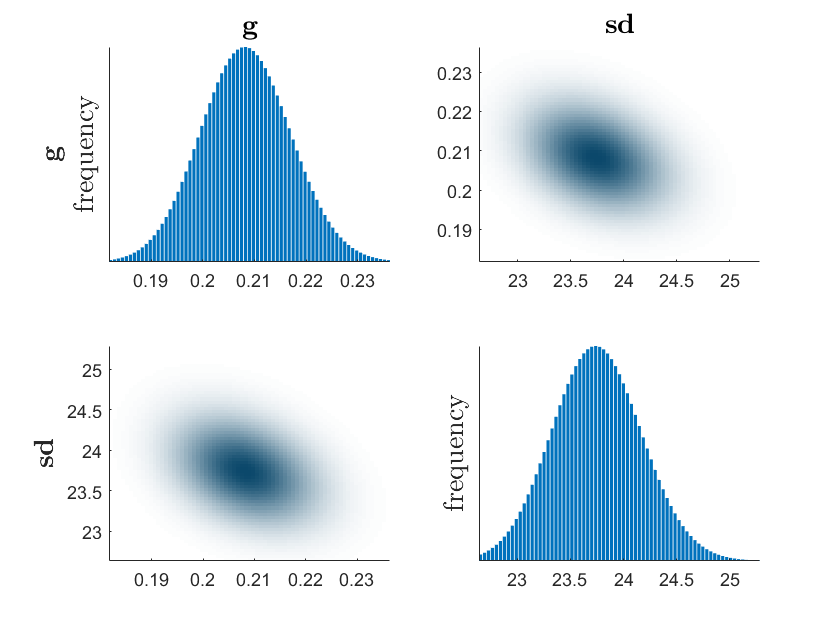



% We fit the data using GridSearch and obtain the posterior. We call this
% fullPosterior, since it came from GridSearch (although in reality it is only 
% proportional to the posterior, it is not the true posterior distribution);
% the results from MCMC we call posteriorSamples. 

% Then we call the plot function PlotPosterior, which takes either a 
% fullPosterior or posteriorSamples as the first parameter, and the names of the 
% model’s parameters as the second parameter. More advanced uses of the MemToolbox 
% will generally require separate calls to the MemFitting and MemPlots functions.

fullPosterior = GridSearch(data, model, 'PosteriorSamples', fit.posteriorSamples);
PlotPosterior(fullPosterior, model.paramNames);

## VariablePrecisionModel with more parameters

**VariablePrecisionModel has three parameters: **

**(1) Guess rate (g)**

**(2) Mean of the precision (mnSTD)(J bar)**

**(3) Standard deviation of the precision (stdSTD). **

**VariablePrecisionModel returns a structure for an infinite scale mixture. **

In such a model, **the standard deviations of observers' reports are assumed to be themselves drawn from a higher-order variability distribution**, rather than always fixed. 

In stats, the term **higher-order statistics** (**HOS**) refers to functions which use the third or higher power of a sample. While the lower order stats use constant, linear, and quadratic terms (zeroth, first, and second powers). The third and higher moments, as used in the s kewness and kutosis, are examples of HOS, whereas the first and second moments, as used in the mean (first), and variance (second) are examples of low-order statistics. HOS are particularly used in estimation of shape parameters, such as skewness and kurtosis, as when measuring the deviation of a distribution from the normal distribution. On the other hand, due to the higher powers, HOS are significantly less robust than lower-order statistics.

This example also gives you a peak at another feature of the MemToolbox – custom model plots. When you call MemFit with the VariablePrecisionModel, it not only creates the graphs you are used to seeing -- the posterior plot, the paralell coordinates plot, and the posterior predictive – it also creates another, fourth plot. This is because the **VariablePrecisionModel includes a function called .modelPlot**

The custom model plot shows the **higher-order distribution on precision, with the MAP parameters displayed in solid green and other samples from the posterior shown with their color indicating their likelihood**: This helps visualize the meaning of the higher-order parameters. 


Error histogram:   -180 _________.'._________ +180
          Model:   Variable precision model (gamma over precision)
     Parameters:   g, modePrecision, sdPrecision

Just a moment while MTB fits a model to your data...

   Running 4 chains...
   ... not yet converged (200); btw/within variance: 1612240417257515.75
   ... not yet converged (400); btw/within variance: 3.47
   ... not yet converged (600); btw/within variance: 4.83
   ... not yet converged (800); btw/within variance: 4.54
   ... not yet converged (1000); btw/within variance: 3.23
   ... not yet converged (1200); btw/within variance: 16.62
   ... not yet converged (1400); btw/within variance: 15.01
   ... not yet converged (1600); btw/within variance: 17.63
   ... not yet converged (1800); btw/within variance: 16.88
   ... not yet converged (2000); btw/within variance: 7.38
   ... not yet converged (2200); btw/within variance: 7.44
   ... not yet converged (2400); btw/within variance: 6.08
   ... not yet converged (2600)

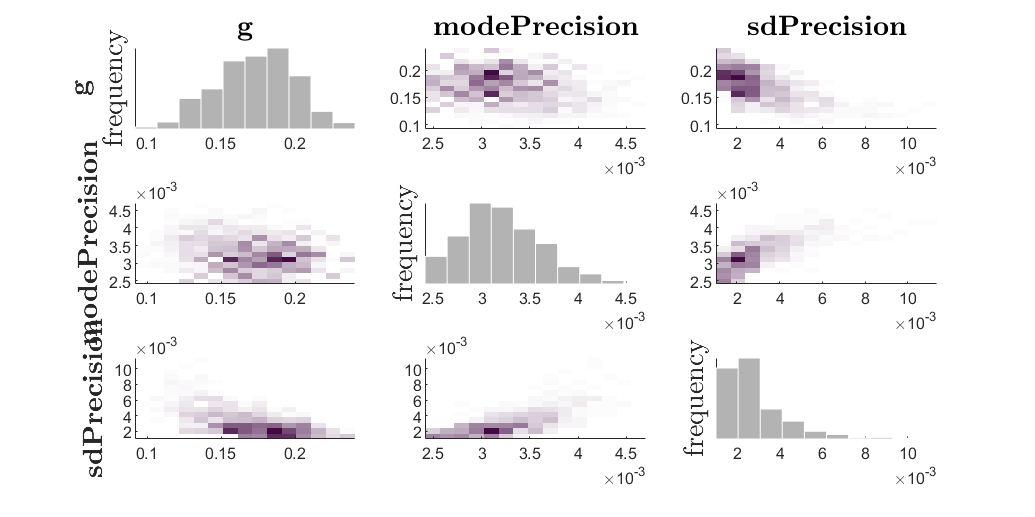

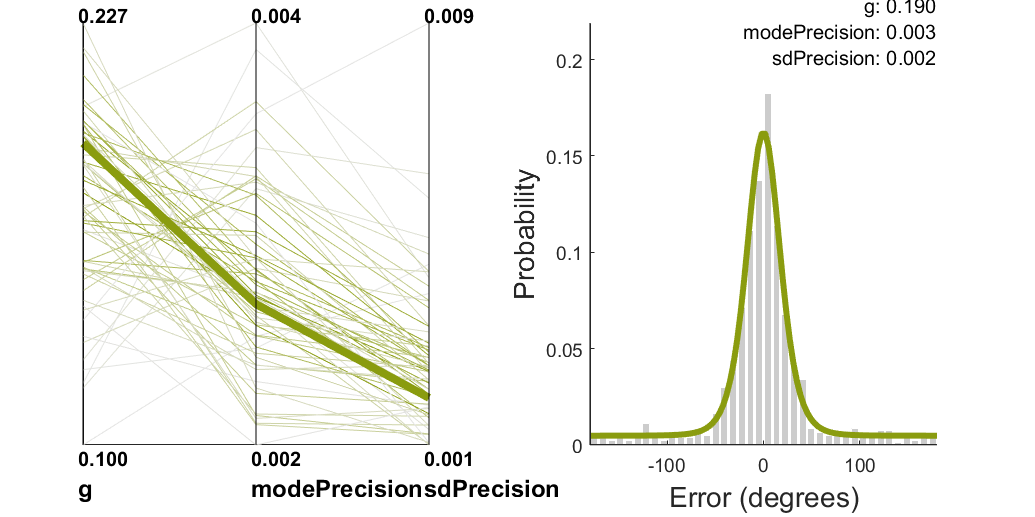

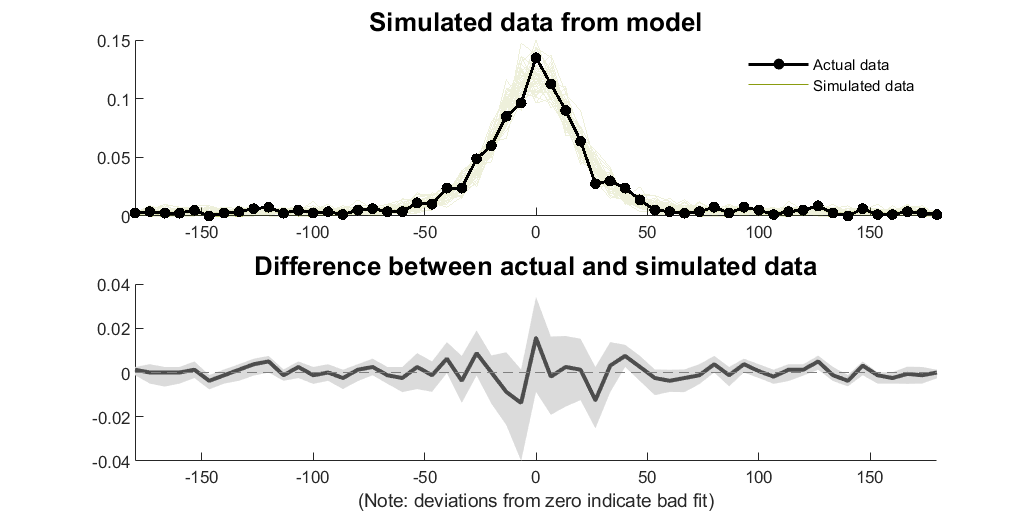

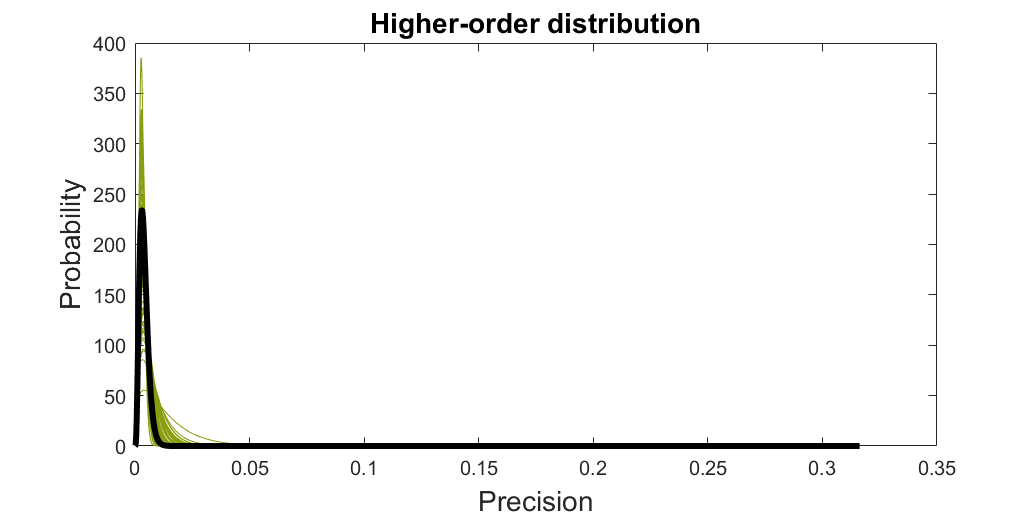


This analysis was performed using MemToolbox version 1.0.0.



clear all;
data = MemDataset(9);
fit = MemFit(data, VariablePrecisionModel_GammaPrecision);


Error histogram:   -180 _________.'._________ +180
          Model:   Variable precision model (gamma over precision)
     Parameters:   g, modePrecision, sdPrecision

Just a moment while MTB fits a model to your data...

   Running 4 chains...
   ... not yet converged (200); btw/within variance: 4.85
   ... not yet converged (400); btw/within variance: 1369009021986338.25
   ... not yet converged (600); btw/within variance: 4.97
   ... not yet converged (800); btw/within variance: 1.89
   ... not yet converged (1000); btw/within variance: 10.32
   ... not yet converged (1200); btw/within variance: 3.34
   ... not yet converged (1400); btw/within variance: 5.26
   ... not yet converged (1600); btw/within variance: 3.10
   ... not yet converged (1800); btw/within variance: 1.96
   ... not yet converged (2000); btw/within variance: 1.27
   ... not yet converged (2200); btw/within variance: 1.08
   ... not yet converged (2400); btw/within variance: 1.18
   ... chains converged after 2600

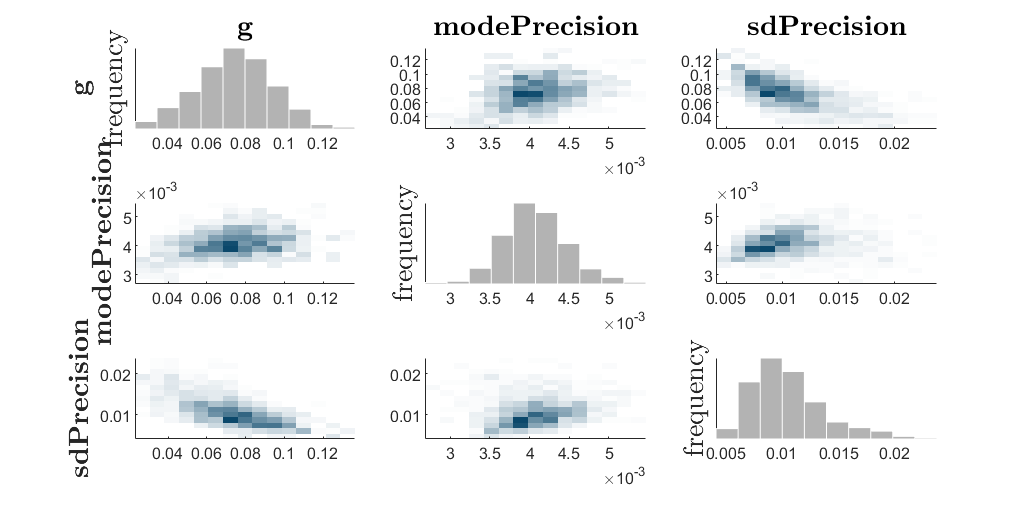

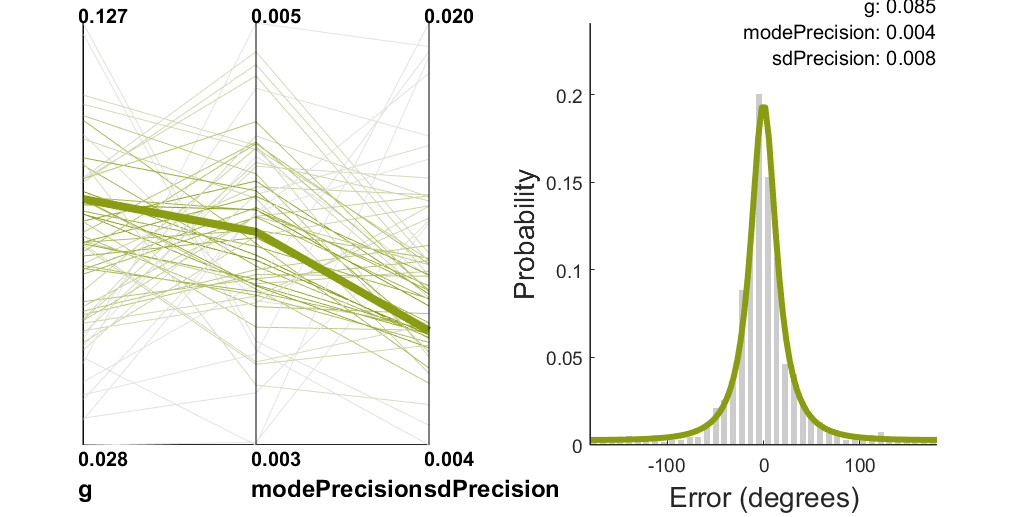

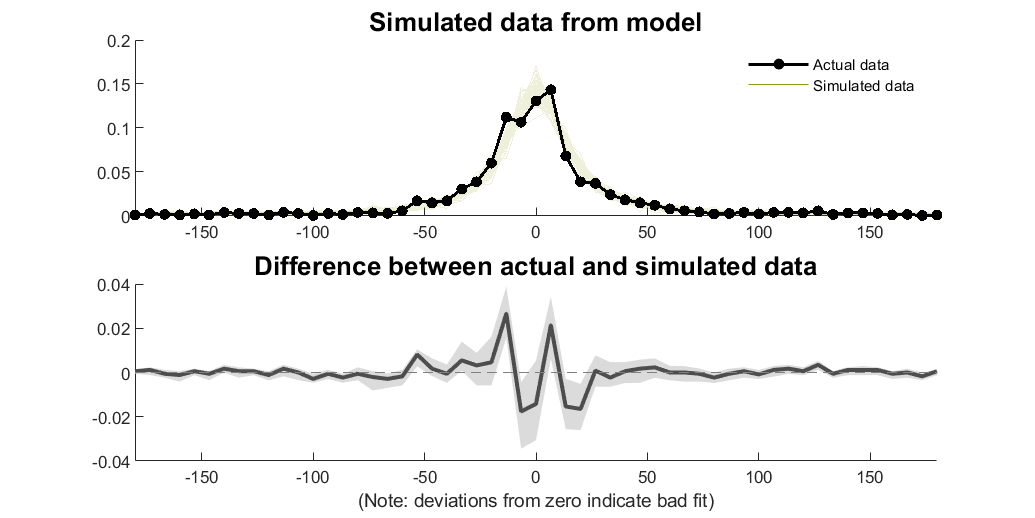

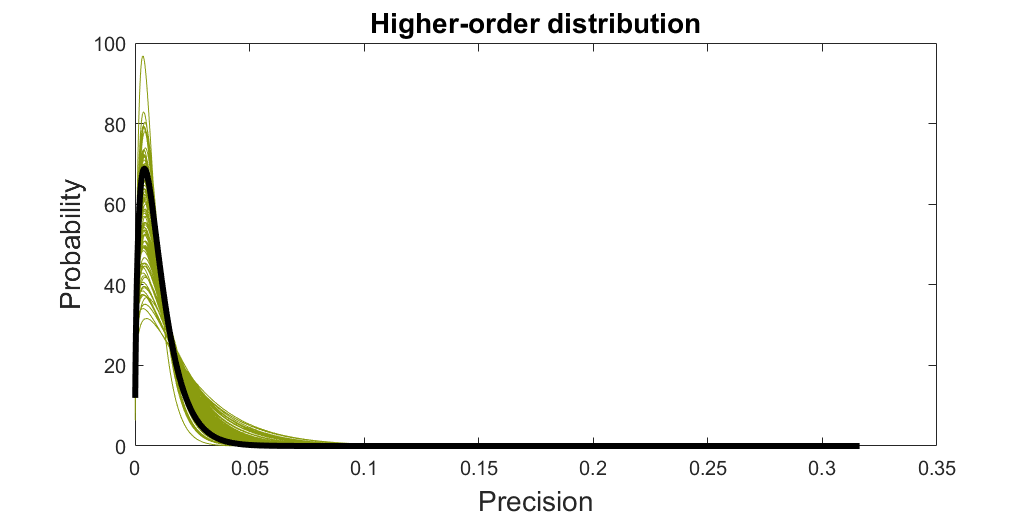


This analysis was performed using MemToolbox version 1.0.0.



% Dataset 'vandenbergetal2012' is data from van den Berg et al. (2012). When
% chosen, requires two additional parameters. The first is a string, either
% 'color' or 'orientation', and determines the task: remembering a color or
% an orientation. The second is a participant. For color, the available
% participants are 'cc','clc','ela','hml','jv','kw', 'mbc', 'mt','rjj','ss',
% 'stp','wc', and 'wjm'. For orientation, the available participants are
% 'AA','ACO','ELA','RGG','TCS', and 'WJM'.

clear all;
data = MemDataset('vandenbergetal2012',1,1);
% i called 1 subject 'cc' in color exp.
fit = MemFit(data, VariablePrecisionModel_GammaPrecision);